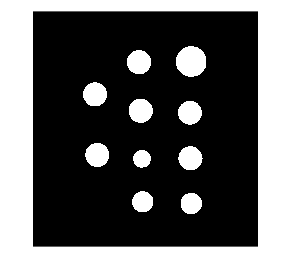


%testImageIdx = randi([1,3]
idx = 3;
testCoinImage = imread("testCoinImage"+idx+".png");
[bwcoinsegmented, maskedcoin] = segmentImage(testCoinImage);
figure, imshow(bwcoinsegmented);

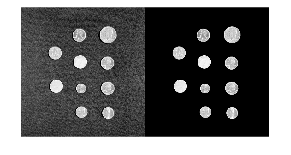

img2 = testCoinImage;
img2(repmat(~bwcoinsegmented,1,1)) = 0;
montage({testCoinImage,img2})

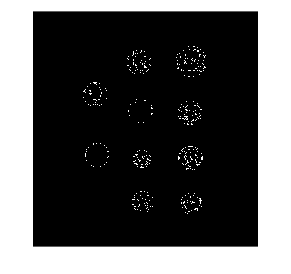

imgedge = edge(img2);
imshow(imgedge);

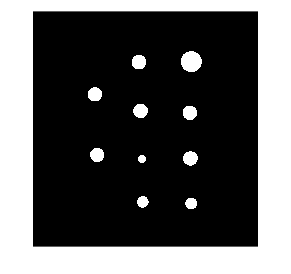

[img3, maskedcoin2] = erodedmask(testCoinImage);
imshow(img3);

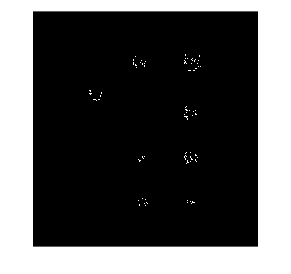

imgedge(repmat(~img3,1,1)) = 0;
imshow(imgedge);

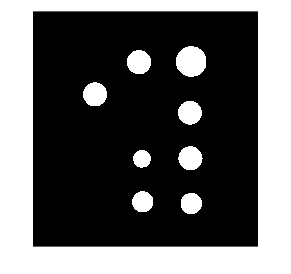

faceEdgeMask = im2uint8(imgedge);
[img4, maskedcoin3] = dilateimage(faceEdgeMask);
img5 = img4 & bwcoinsegmented;

imshow(img5)


stats = regionprops('table',img5,'Area','Centroid',...
    'MajorAxisLength','MinorAxisLength')

stats = 8×4 table
    Area         Centroid        MajorAxisLength    MinorAxisLength
    _____    ________________    _______________    _______________

     7766    256.92    343.27        99.462             99.428     
     7877    438.56    210.46        100.19             100.12     
     6070     454.3    787.67        87.948             87.891     
     4192    450.95    609.98        73.116             73.015     
    12573    654.65    207.88        126.61             126.45     
     7680    649.17    419.58        98.987             98.799     
     7782    651.26    607.82        99.579             99.516     
     6166    654.53    794.56        88.641             88.582     


n_cents = sum(stats.Area > 12000)

n_cents = 1

n_quater = sum(stats.Area > 7600 & stats.Area < 7900)

n_quater = 4

n_nickel = sum(stats.Area > 6000 & stats.Area < 6500)

n_nickel = 2

n_dime = sum(stats.Area <4900)

n_dime = 1


USD = n_cents * 0.50 + n_quater * 0.25 + n_nickel * 0.05 + n_dime * 0.10

USD = 1.7000